# Practice 1: Energy Expenditure and Smartphones

This is a [matlab function](https://it.mathworks.com/help/matlab/matlab_prog/create-functions-in-files.html), sought for buffering and processing acceleration data according to ***lecture 1-3***. Remember to download the entire folder **Practice_1-EnergyExpenditure**, and store it either locally in your computer or in your [Matlab Drive](https://drive.matlab.com/).  In the later case, after you uploaded the material to your Matlab Drive, matlab functions and scripts can be written and launched directly in [Matlab Online](https://it.mathworks.com/products/matlab-online.html).

## How should students complete this Matlab function?

Complete the code below to compute the time integral of the absolute value of acceleration data and sum them over the three axes.  This implies:

- filtering the buffered data

- summing the abolute values of the filtered data

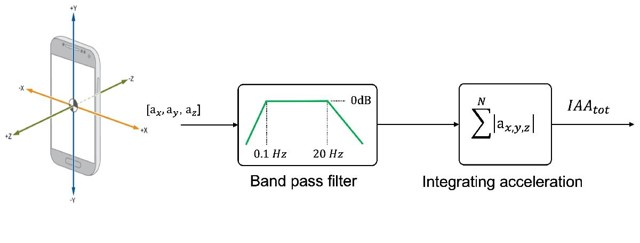

The code is to be run as a [matlab function](https://it.mathworks.com/help/matlab/matlab_prog/create-functions-in-files.html), taking three input arguments and providing user with a scalar, as per the scheme below:

### Input arguments

- `axyz`: 2D matrix with N (time samples) rows and three columns, with the accelaration ($a_x$, $a_y$, $a_z$) values in the $x$, $y$, and $z$ axes respectively.

- `filter_acceleration`: boolean indicating whether buffered acceleration is to be filtered or not.  This variable was sought to allow students to appreciate the effect of gravity on the energy expenditure estimates.

- `sf`: sampling frequency used to collect acceleration data.

### Output arguments

- `IAAtot`: single element variable, containing the sum of the integrated, absolute, acceleration values (cf. below and ***lecture 1-3***).

## The code - matlab function

The code is partly completed, with the sole aim of providing students with one of many possible solutions.

Start using the standard definition statement for creating matlab functions

function IAAtot = fromBufferedAccToIaaTot(axyz,filter_acceleration,sf)

### Definition of parameters

The only parameters to be defined here are the coefficients for the band-pass filter (`a` and `b`), according to the cutoff frequencies indicated above.  Students are welcome to try different cutoffs and evaluate how much they affect results, mainly in **Task 1.2.3**, when **EE** is to be computed.  When reasoning on which filter coefficients and procedure to apply, remember that each block of 30 s of acceleration data is to be filtered independently.

% code here

### Processing acceleration data

Two steps are to be conducted here:

#### 1. Filtering buffered data

The first processing step is band-pass filtering, necessary mainly for attenuating the effect of gravity associated with changes in the attitude.

% code here

#### 2. Integrating acceleration

As described by Bouten and colleagues (1998), the output of this function ${\textrm{IAA}}_{\textrm{tot}}$ is computed by summing the integrated, absolute value of individual acceleration components over the three axes:

with each of the terms in the right hand side of the equation being defined as:

        

Use the trapezoidal integration method (described during the lecture) with a fixed sampling interval $\textrm{dt}=\frac{1}{s_f }$ for computing ${\textrm{IAA}}_i$

% code here